## `Question 01`

`Generate a binary sequence of length L = 1000, considering D 2 f0; 1g and Pr(D = 0) = Pr(D = 1) = 1/2: Use the binary sequence to generate a stream of rectangular pulses of amplitude S, where S belongs to +-A with A = 1.  `

% defining variables

L = 1000;  % binary sequence of length.
A = 1;
miu = 0;
sigma = 1;
tau = 0;

% generating the random bit stream of length L

D = ones(1,L); % create an array of length of ones. dimension = 1 x L

rand = randperm(L, L/2); % generate random indexes with length of half of sequence length  within sequence.
D(rand) = zeros(1, L/2); % replace the D sequence with zeros for random indexes.

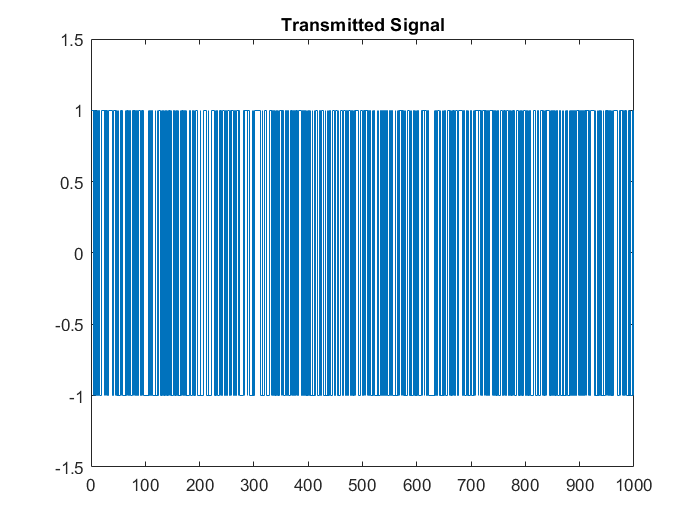

% generate a stream of rectangular pulses

Z = zeros(1, L); % generating a empty zero array as pulse

for index1 = 1:L
    if D(index1) == 1
        S(index1) = A;   % if bit is equal to one assign it as +1
    
    else
        S(index1) = -1 * A;   % if bit is equal to zero assign it as -1
    end
end

% plotting the transmitted signal 
figure;
stairs([1:L], S);
ylim([-1.5 1.5]);
title("Transmitted Signal")

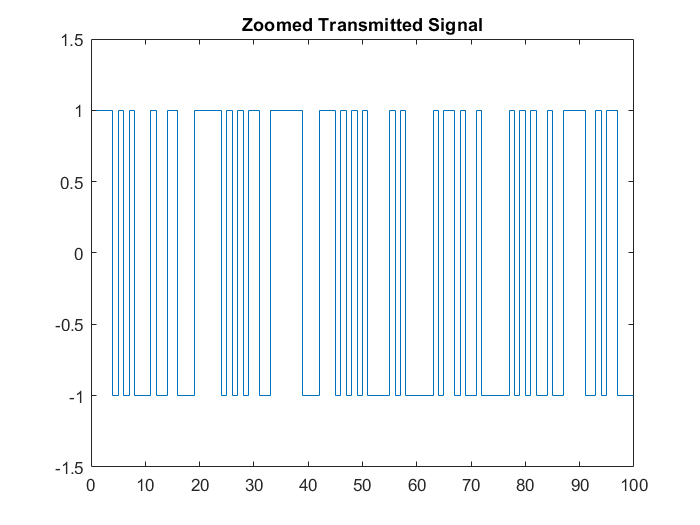


% Zoomed version of Tx Signal
figure;
stairs([1:L], S);
ylim([-1.5 1.5]);
xlim([0 100]);
title("Zoomed Transmitted Signal")

## `Question 02`

`Generate an AWGN sequence, also of length L = 1000, considering ``σ`

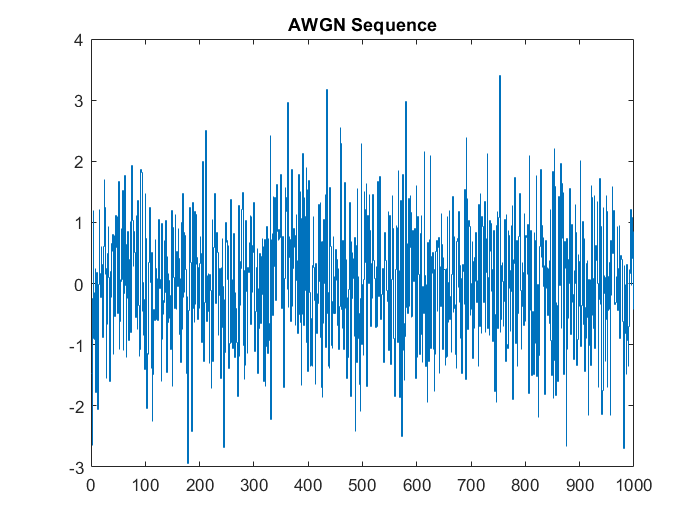

N = miu + sigma*randn(1,L); % generate normal distributed random numbers with mean (miu) and standard deviation (sigma)
figure;
stairs([1:L],N);
title("AWGN Sequence")

## `Question 03`

`Plot the sequence of ``R ``and observe the impact of the variance of noise on  R` `by varying ``σ``2 .`

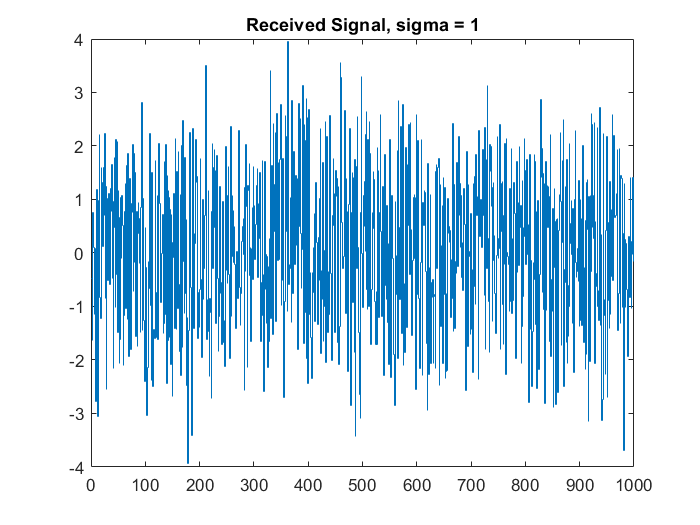

R = S + N; %  add AWGN to the Tx signal 

figure; % plot the Received signal
stairs([1:L],R);
title("Received Signal, sigma = 1")

## `Question 04`

`Sketch and compare the sequence of ``Y ``with the transmitted signal.  `

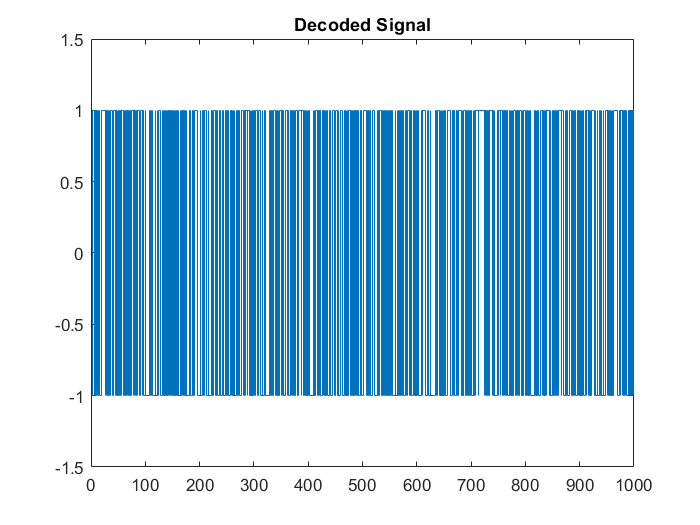

% generate a sequence of Y

Y = zeros(1, L); % generating a empty zero array

for index2 = 1:L
    if R(index2) > tau
        Y(index2) = A;   % if value is greater than threshold(tau) assign it as +1
    
    else
        Y(index2) = -1 * A;   % if value is less than or equal to threshold(tau) assign it as -1
    end
end

% plot the decoded signal
figure;
stairs([1:L], Y);
ylim([-1.5 1.5]);
title("Decoded Signal")

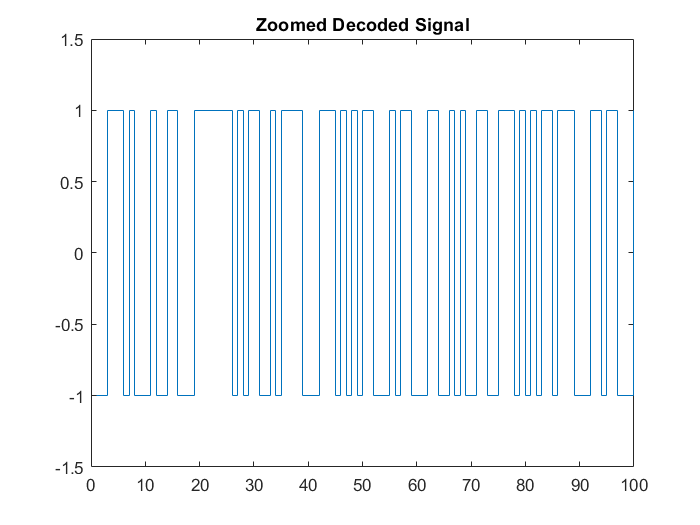


% plot the zoomed decoded signal
figure;
stairs([1:L], Y);
ylim([-1.5 1.5]);
xlim([0 100]);
title("Zoomed Decoded Signal")